# Stability analysis of discrete time control structures

## Theoretical aspects

-  Stability analysis (Jury's stability criterion)

- Root Locus for discrete-time systems

- Grid of constant damping factors and natural frequencies

- Matlab functions: *c2d, rlocus, zgrid, feedback, pzmap*

## Negative feedback structures with data sampling

### Stability analysis depending on the proportional gain, k

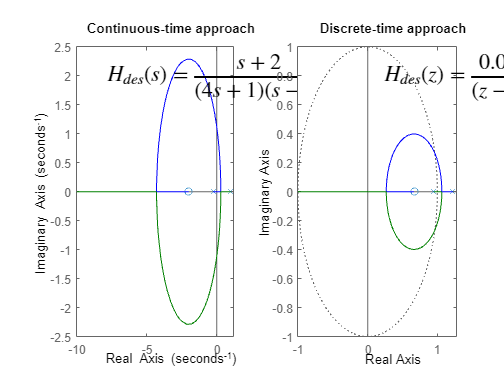

%% S1: - Stability analysis depending on k
clear;% erase all the existing workspace variables
num=[1 2];den=[4 -3 -1];% the nominator and denominator of the process
Hp=tf(num,den);% the process transfer function
T=0.2;% the sampling period
Hdes=c2d(Hp,T,'zoh');% the open loop discrete time transfer function
subplot(121);rlocus(Hp);title('Continuous-time approach');
text(-8,2,'$H_{des}(s)=\frac{s+2}{(4s+1)(s-1)}$','Interpreter','Latex','FontSize',18)
subplot(122);rlocus(Hdes);title('Discrete-time approach')

text(0.2,0.8,'$H_{des}(z)=\frac{0.064563 (z-0.6655)}{(z-1.221) (z-0.9512)}$','Interpreter','Latex','FontSize',18)

### Dynamic behaviors depending on the proportional gain k

Evaluating the pole location depending on the gain k, varied inside the stable interval $\left(3\ldotp 76,40\ldotp 3\right)$, the next types can be obtained:

- $k=3\ldotp 76,\zeta =0$, UNDAMPED system, both poles are located exactly on the unity circle

- $k\in \left(3\ldotp 76,25\ldotp 4\right),\zeta \in \left(0,1\right)$, UNDERDAMPED system, pair of complex conjugated poles, inside the unity circle

- $k=25\ldotp 4\ldotp \zeta =1$, CRITICALLY DAMPED system, real pole with multiplicity order 2

- $k\in \left(25\ldotp 4,40\ldotp 3\right),\zeta >1$, OVERDAMPED system, two real and distinctive poles, inside the unity circle

- $k=40\ldotp 3,\zeta =0$, UNDAMPED system, one pole located exactly on the unity circle (in -1)

### Damping ratio ($\zeta$) constant locus

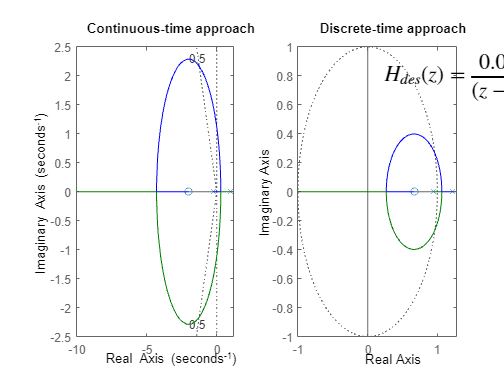

%% S2: - damping ratio constant locus ζ = 0.5 (σ ≈ 16% )
subplot(121);rlocus(Hp);title('Continuous-time approach');sgrid(0.5,[]);

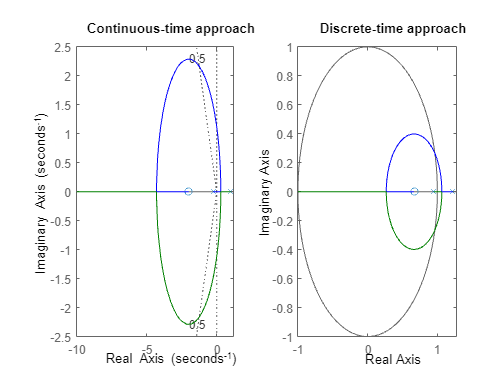

subplot(122);rlocus(Hdes);title('Discrete-time approach');zgrid(0.5,[])

## Problems

### 3.1 For the next time control structure with the sampling period T=0.05sec

clear variables;

k=1;
s=tf('s');
T = 0.05;
Hc = k/s;
Hp = 2400/(s+20)/(s+40);
Hd = Hc * Hp;

1. Discretize the controller ($H_c \left(s\right)=\frac{k}{s}$) using tustin (bilinear) transformation

Hc = c2d(Hc,T,'tustin')

Hc =
 
  0.025 z + 0.025
  ---------------
       z - 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.



2. Discretize the process ($H_p \left(s\right)=\frac{2400}{\left(s+20\right)\left(s+40\right)}$) using zero order hold method

Hp = c2d(Hp,T,'zoh')

Hp =
 
      1.199 z + 0.441
  ------------------------
  z^2 - 0.5032 z + 0.04979
 
Sample time: 0.05 seconds
Discrete-time transfer function.



3. Use *zpk *function to write on your notebook the open loop transfer function

Hd = Hc*Hp;
Hd = zpk(Hd)

Hd =
 
   0.029968 (z+1) (z+0.3679)
  ---------------------------
  (z-1) (z-0.3679) (z-0.1353)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



4. Analyze the stability of the closed loop system depending on $k\in \left(0,\infty \right)$; draw on your notebook the root locus and mention the obtained values of k directly on the graphics

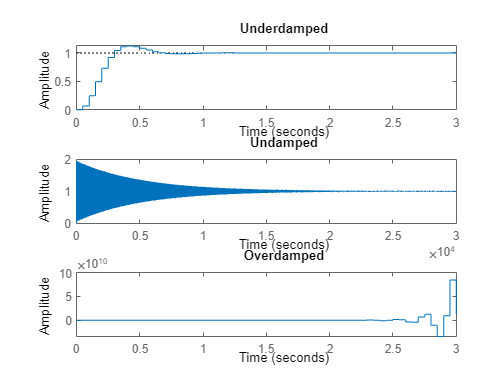

Hc = k/s;
Hc = c2d(Hc,T,'tustin');
Hd = Hc*Hp;

figure,
subplot(3,1,1); step(feedback(2.18*Hd,1),3); title("Underdamped")
subplot(3,1,2); step(feedback(9.27*Hd,1)); title("Undamped")
subplot(3,1,3); step(feedback(42*Hd,1),3); title("Overdamped")

5. Analyze closed loop behavior depending on $k\in \left(0,\infty \right)$; use Matlab to generate the closed loop step response for all different behaviors that result depending on k; give suggestive titles to the generated plots

H0 = feedback(Hd,1); 

6. Use the zgrid function to obtain the value of k for which the overshoot of the closed loop is below 10%

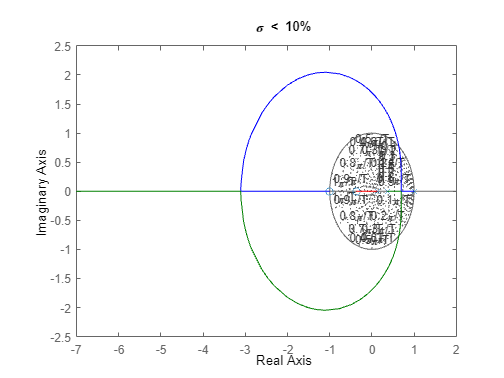

figure,
rlocus(Hd); zgrid
title('\sigma < 10%')

7. Generate the step response of the closed loop when the damping ratio is 5.5

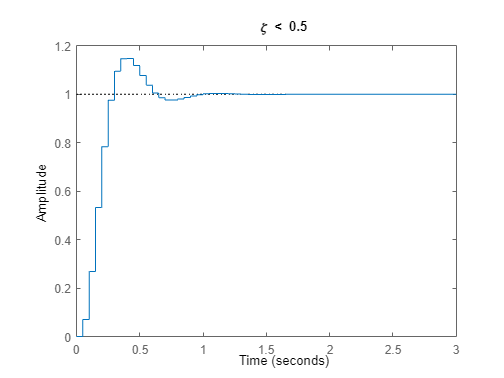

figure,
step(feedback(2.36*zpk(Hd),1),3)
title('\zeta < 0.5')